clc
close all;
clear;     

tic

filename = '3BlancosB.txt';
load('mean_noise.mat');

noisePercent = 0.5;

fid = fopen(filename,'r');
if fid == -1
    error('No se pudo abrir %s', filename);
end
C = textscan(fid, '%s', 'Delimiter', '\n');
fclose(fid);

% Extraer la primera (y única) celda y convertirla a string array
strLines = string(C{1});

% 2) Eliminar prefijo "0x" de todas las líneas
strLines = extractAfter(strLines, "0x");

% 3) Pasar a 2 filas × numBloques columnas
numBloques = numel(strLines)/2;
S = reshape(strLines, 2, numBloques);

% 4) Radar: extraer I y Q
hex1 = S(1,:);                              % señales radar
I_hex = extractBetween(hex1, 1, 4);         % primeros 4 dígitos
Q_hex = extractBetween(hex1, 5, 8);         % siguientes 4 dígitos
I_val_16 = hex2dec(I_hex).';                % convierto todo de golpe
Q_val_16 = hex2dec(Q_hex).';
I_radar = bitshift(I_val_16, -4) * (1/4096) - 0.475;           % quito 4 bits
Q_radar = bitshift(Q_val_16, -4) * (1/4096) - 0.475;

% 5) Sync y brújula
hex2 = S(2,:);
sync_hex    = extractBetween(hex2, 1, 4);
compass_hex = extractBetween(hex2, 5, 8);
sync_signal = hex2dec(sync_hex).'/32768;
compass_raw = hex2dec(compass_hex).';
compass_real = compass_raw/100 - 80;

**ADAPTACIÓN DE DATOS**

Ix = I_radar;
Qx = Q_radar;
Sx = sync_signal;

c = 299792458; % Velocidad de la luz.
AIrate = 1000000; %datos de la tasa de muestreo para el segundo ROSAR
Ts = 1/AIrate; % periodo de muestreo;
fo = 24e9;  % Frecuencia transmitida 
Bt = 181.5e6; % Ancho de banda transmitido
fm = 1562; % Frecuencia de la señal rampa moduladora.
Tm = 1/fm; % Periodo de la señal moduladora en segundos (Duración de la Rampa total)
Gamma = Bt/Tm;


**OPERACIONES PARA VISUALIZACIÓN DE DATOS RECIBIDOS**

% Graficar las señales I, Q y Sincronismo
% figure;
% hold on;
% hRadarI = plot(I_voltage, 'b-', 'DisplayName', 'Radar I');
% hRadarQ = plot(Q_voltage, 'r-', 'DisplayName', 'Radar Q');
% hSync   = plot(sync_signal, 'g-', 'DisplayName', 'Sincronismo');
% hold off;
% legend show;
% xlabel('Muestras');
% ylabel('Valor');
% title('Señales Radar y Sincronismo');
% 
% % Crear checkboxes para activar/desactivar cada traza
% uicontrol('Style', 'checkbox', 'String', 'Radar I', 'Value', 1, ...
%     'Position', [20 20 100 20], 'Callback', @(src, event) togglePlot(hRadarI, src));
% uicontrol('Style', 'checkbox', 'String', 'Radar Q', 'Value', 1, ...
%     'Position', [20 50 100 20], 'Callback', @(src, event) togglePlot(hRadarQ, src));
% uicontrol('Style', 'checkbox', 'String', 'Sincronismo', 'Value', 1, ...
%     'Position', [20 80 100 20], 'Callback', @(src, event) togglePlot(hSync, src));
% 
% 
% disp('Valores reales de la brújula (valor entero/100):');
% disp(compass_real);
% 
% % Función auxiliar para alternar la visibilidad de cada traza
% function togglePlot(hPlot, src)
%     if src.Value
%         set(hPlot, 'Visible', 'on');
%     else
%         set(hPlot, 'Visible', 'off');
%     end
% end

**NUEVO: ELIMINACIÓN DE LAS MUESTRAS EN LAS QUE NO HAY MOVIMIENTO**

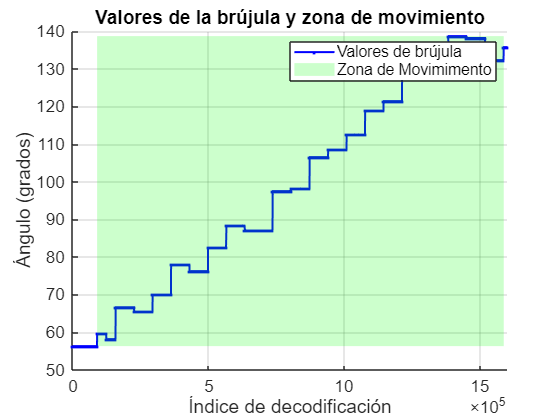

compass_real = compass_real';

% === PARTE 1: Almacenar solo los cambios significativos de la brújula ===
tolerance = 0.2;  % Tolerancia para considerar un cambio significativo

diff_circ = abs(mod(diff(compass_real) + 180, 360) - 180);
indices_cambios = find(diff_circ >= tolerance) + 1;

idxInicio = indices_cambios(1);
idxFin    = indices_cambios(end);

% Filtrar las señales para conservar solo las muestras durante el movimiento
Ix = Ix(idxInicio:idxFin);
Qx = Qx(idxInicio:idxFin);
Sx = Sx(idxInicio:idxFin);

figure; 
hold on;
plot(compass_real,          'b.-', 'LineWidth', 1.5);

x_patch = [idxInicio, idxFin, idxFin, idxInicio];
ymin    = min(compass_real);
ymax    = max(compass_real);
y_patch = [ymin, ymin, ymax, ymax];
patch(x_patch, y_patch, 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');

legend('Valores de brújula', 'Zona de Movimimento');
xlabel('Índice de decodificación');
ylabel('Ángulo (grados)');
title('Valores de la brújula y zona de movimiento');
grid on;
hold off;

**OBTENCIÓN MUESTRAS CORRECTAS**

pointsAdquisition = size(Ix,1); % Número de muestras totales. Dimension de las filas (1), columnas sería (2).
ceros = Sx;

% En esta parte eliminamos la señal hasta la primera rampa válida

inicioRampaDown = find(ceros==0); % inicioRampaDown son todos los indices de las muestras que son 0
posicionInicioRampaDown = inicioRampaDown(1); % Indice de la primera transición de 1 a 0

% Eliminamos la parte de la señal hasta el final de la primera rampa
I = Ix(posicionInicioRampaDown:end,:);
Q = Qx(posicionInicioRampaDown:end,:);
S = Sx(posicionInicioRampaDown:end,:);
ceros = ceros(posicionInicioRampaDown:end-1,:);
ceros = vertcat(ceros,0); %Se añade un cero al final de la señal ceros

inicioRampaUp = find(ceros==1); % inicioRampaDown son todos los indices de las muestras que son 1
posicionInicioRampaUp = inicioRampaUp(1)-1; % Indice de la primera transición de 0 a 1 (rampa)

% Eliminamos la parte de la señal hasta el inicio de la primera rampa
I = I(posicionInicioRampaUp:end,:);
Q = Q(posicionInicioRampaUp:end,:);
S = S(posicionInicioRampaUp:end,:);
ceros = ceros(posicionInicioRampaUp:end,:);
cerosTraspuesta = ceros'; % Se traspone ceros, teníamos una columna ahora tendremos una fila
cambioBajo_Alto = strfind(cerosTraspuesta,[0 1]); % Encuentra las posiciones donde hay cambio de "0" a "1", esto será donde hay inicios de ciclo.

% Convertimos I y Q y eliminimamos todos los valores que no estan en el duty cicle de la señal de sincronismo.
I = (I.*ceros)';
Q = (Q.*ceros)';

%sizeVectorI = size(I,2); % Tamaño de la señal I, que es el mismo que el de Q
tiempoAdquision = pointsAdquisition / AIrate; %Tiempo de adquisición que serán los puntos de adquisición (muestras totales) entre las muestras/segundo
angMin_rad = compass_real(idxInicio)* (pi/180); % Ángulo mínimo de la brújula
angMax_rad = compass_real(idxFin)* (pi/180); % Ángulo máximo de la brújula
%numeroRampas = (tiempoAdquision / Tm); % Número de rampas enviadas por el radar
W_gra = abs(angMax_rad - angMin_rad)/ ( tiempoAdquision * (pi/180)) ; %Cálculo de la velocidad angular en unidades lineales
W = W_gra*(pi/180); % velocidad angular en radianes por segundo.

muestrasRampaUp = 444; % Número de muestras tomadas para la rampa de subida

tRampaSubida = muestrasRampaUp*Ts; % Tiempo de rampa de subida, número de muestras * tiempo por muestra
tRampaBajada = ((floor(Tm/Ts))-muestrasRampaUp)*Ts; % Se resta el numero de muestras totales al de subida por el tiempo por muestra, floor redondea hacia abajo
Dm = tRampaSubida/(tRampaSubida+tRampaBajada); % Ciclo de trabajo de la señal moduladora [ t_rampa_subida/(t_rampa_subida+t_rampa_bajada) ]

t_ini_proces = 0;
t_fin_proces = tRampaSubida; 
Te = t_fin_proces - t_ini_proces; % Periodo de la señal moduladora efectivo (en el que se procesa).
st_ini = 0; % Inicio del tiempo lento (slow time), recordar que el slow time es el peridodo de la rampa y el fast time es cada muestra de la señal
st_fin = (((angMax_rad - angMin_rad) / W)); % Fin del tiempo lento (slow time) 

t = (t_ini_proces : Ts : t_fin_proces); % Vector de tiempo rápido (fast time) desde t_ini_proces hasta t_fin_proces con pasos de Ts (tiempo de cada muestra)
st = (st_ini : Tm : st_fin); % Vector de tiempo lento (slow time) desde st_ini hasta st_fin con pasos de Tm (tiempo de cada rampa)
anglesOfRamps = angMin_rad/(pi/180) + (W_gra*st); % Angulos en grados correspondientes a cada instante de slow time, es decir, cada rampa.
sizeanglesOfRamps = size(anglesOfRamps,2); % Tamaño del vector de los ángulos de cada rampa

matrizAlmacenarI = zeros(size(cambioBajo_Alto,2),muestrasRampaUp+1); % Matriz de ceros con filas igual al número de transiciones cambioBajo_Alto y columnas igual a muestrasRampaUp + 1.
matrizAlmacenarQ = zeros(size(cambioBajo_Alto,2),muestrasRampaUp+1); % Matriz de ceros con filas igual al número de transiciones cambioBajo_Alto y columnas igual a muestrasRampaUp + 1.

Itemp = I; % Copia de la señal I
Qtemp = Q; % Copia de la señal Q

sizeCambioBajo_Alto = size(cambioBajo_Alto,2); % Tamaño de los cambios de bajo a alto
contador = 0;

% Recorre cada transición detectada en cambioBajo_Alto excepto la última.
% Guarda en matrizAlmacenarX las partes de la señal que coinciden con las
% rampas de subida
for i = 1:sizeCambioBajo_Alto-1
    matrizAlmacenarI(contador+1,:) = Itemp(1,(cambioBajo_Alto(i)+1):(cambioBajo_Alto(i)+(muestrasRampaUp+1)));
    matrizAlmacenarQ(contador+1,:) = Qtemp(1,(cambioBajo_Alto(i)+1):(cambioBajo_Alto(i)+(muestrasRampaUp+1)));
    contador = contador+1;
end

% Recorta las matrices matrizAlmacenarI y matrizAlmacenarQ para mantener solo las filas correspondientes al número de ángulos procesados (sizeanglesOfRamps).
matrizAlmacenarI = matrizAlmacenarI(1:sizeanglesOfRamps,:);
matrizAlmacenarQ = matrizAlmacenarQ(1:sizeanglesOfRamps,:);

% Calculo de los rangos máximo y mínimo con la formula de conversión de
% frecuencia de batido a distancia
% r_max = Dm *(c/(2*Bt))*(fb_max/fm);
% r_min = Dm *(c/(2*Bt))*(fb_min/fm);

t_size = size(t,2); % Número de elementos en el vector de tiempo rápido
st_size = size(st,2); % Número de elementos en el vector de tiempo lento

t_AImod_Total = zeros(st_size,t_size); % Matriz de ceros con filas igual a st_size y columnas igual a t_size.
% Para cada instante de tiempo lento st(i), suma el vector de tiempo rápido t y almacena el resultado en la fila correspondiente de t_AImod_Total.
t_AImod_Total = st(:) + t;

Sgn_Com = (matrizAlmacenarI+1i*matrizAlmacenarQ); % Señal compleja total de I + jQ
Sgn_Com = Sgn_Com - mean_noise*noisePercent;

**COMPRESIÓN EN RANGO**


%Ventana de Hamming a cada rampa (slow time)
[~, sgnModSize] = size(Sgn_Com);
win = hamming(sgnModSize).';
wMod = repmat(win, st_size, 1);
Sgn_Windowed = (Sgn_Com .* wMod)';

Sgn_Total = (Sgn_Com.*wMod)'; % Se multiplica cada elemeto de la señal compleja con la ventana Hamming

nfft = 2048; % Número de puntos para la FFT, define la resolución espectral
Sgn_fft = fft(Sgn_Total,nfft); % FFT de la señal compleja con la señal con la ventana aplicada
Sgn_fft = Sgn_fft(5:250,:); % Seleccion de los puntos desde el 15 hasta el 250 de la fft,  Elimino la segunda mitad de la fft (se toma la parte superior del espectro de frecuencia), el 15 es para eliminar potencia de ruido en el inicio.
Sgn_fftMod = abs(Sgn_fft); % Modulo de la señal

% PotSgn_dB = 20*log10(Sgn_fftMod); % Transformacióna potencia en dB's
frec=(0:((nfft/2)-1))/nfft*AIrate; % Se calculan las frecuencias de la FFT (f=((k-1)/N)*fs) correspondientes a cada bin, punto de la FFT
frec=frec(:,5:250); % frec solo contiene las frecuencias correspondientes a los bins del índice 15 al índice 250.

Kr = Bt/(Tm); % Tasa de chirp, es decir, ancho de banda entre el tiempo de modulacion, como varía la frecuencia de la señal transmitida
% Variacion por unidad de tiempo de la frecuencia de un chirp.

ejeR = 1.3*((c/(2*Bt)).*(frec/(fm))-7.23) + 7.34; % Calculo del rango correspondiente a cada frecuencia de batido

**COMPRESIÓN EN AZIMUTH ( Sin detecciones ni cálculo centroide)**

deltaR_real   = c/(2*Bt);
[samplesFt, samplesSt] = size(Sgn_fft);
numAngles     = numel(anglesOfRamps);
L             = 0.25;       % m
H             = 0;          % m
angleRef      = anglesOfRamps(floor(numAngles/2));
Fcorreccion   = 1;
lamda         = c/fo;

% Calcular r0 y B (elevación) para cada bin de rango
r0 = (0:samplesFt-1).' * deltaR_real;               % [samplesFt×1]
B  = acos( sqrt(max(r0.^2 - H^2, 0)) ./ r0 );       % [samplesFt×1]
B(1) = 89*(pi/180);                                  % caso r0==0

%Preparar término angular
cosB       = cos(B);                                % [samplesFt×1]
phiDelta   = anglesOfRamps - angleRef;              % [1×numAngles]
cosPhi     = cosd(phiDelta);                        % [1×numAngles]

% Montar matriz de distancias rMat para cada (r0, ángulo)
%    rMat(i,j) = sqrt( r0(i)^2 + L^2 - 2*r0(i)*L*cosB(i)*cosPhi(j) )
term1      = r0.^2 + L^2;                            % [samplesFt×1]
term2      = (2 * r0 .* L .* cosB) * cosPhi;        % [samplesFt×numAngles]
rMat       = sqrt(term1 - term2);                   % [samplesFt×numAngles]

% Calcular kernel2Vector
kernel2Vector = exp(1i * Fcorreccion * 4*pi * (rMat - r0) / lamda);  % [samplesFt×numAngles]

% Aplicar ventana de Hamming sobre cada fila (azimuth)
wHam      = hamming(numAngles).';                    % [1×numAngles]
wMod_corr = repmat(wHam, samplesFt, 1);              % [samplesFt×numAngles]
s_kernelCorr = kernel2Vector .* wMod_corr;           % [samplesFt×numAngles]

% Se hace una correlación cruzada entre cada fila de Sgn_fft y de
% s_kernelCorr. Esta correlación mide la similitud entre dos señales
% desplazdas en el tiempo.

nCorr     = 2*samplesSt - 1;
s_flip_conj = conj( fliplr(s_kernelCorr) );  % [samplesFt×samplesSt]

%Calculo la convolucion via FFT en la dimensión 2 (slow-time)
FFT_S = fft( Sgn_fft,      nCorr, 2 );       % [samplesFt×nCorr]
FFT_K = fft( s_flip_conj,  nCorr, 2 );       % [samplesFt×nCorr]

V_full = ifft( FFT_S .* FFT_K, nCorr, 2 );   % conv (circulante -> lineal por padding)

%Módulo al cuadrado de la correlación
x_CorrMod = abs(V_full).^2;                  % [samplesFt×nCorr]

%Recorte como en el bucle original
midPt    = ceil(nCorr/2);                    % índice de lag 0
xCorrIni = midPt - floor(samplesSt/2);
xCorrFin = xCorrIni + samplesSt - 1;

MatrizRecortada = x_CorrMod(:, xCorrIni : xCorrFin);  % [samplesFt×samplesSt]

**Compesación de la atenuación en potencia con el rango**

% Normalización de la potencia (FTC)
dmax = max(ejeR);                              % Rango máximo
correctionFactor = (ejeR / dmax).^4;             % Factor de corrección: (d/dmax)^2
correctionFactor = correctionFactor';

% Multiplicar cada fila de MatrizRecortada por el factor correspondiente.
% Usamos repmat para que correctionFactor se aplique a cada columna.
MatrizRecortada = MatrizRecortada .* repmat(correctionFactor, 1, size(MatrizRecortada,2));

**CFAR**

Descripción de las celdas, en nuetro caso es bidimensional, por lo que estos valores son de forma cuadradas no lineales.

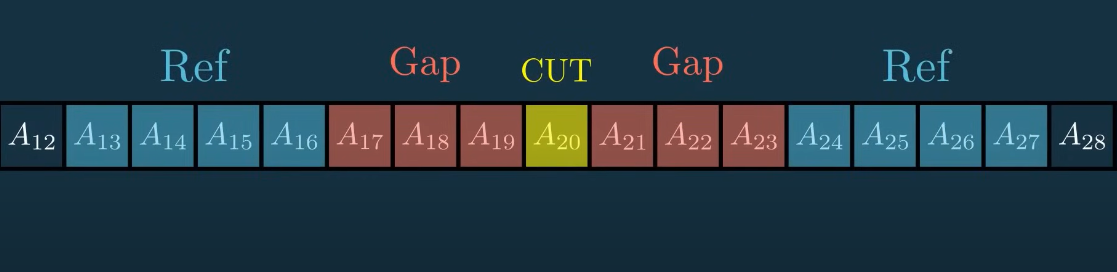

pfa = 1e-7; % Probabilidad de falsa alarma determina el umbral de detección (valores más bajos detectan solo blancos fuertes, valores más altos pueden incluir ruido).
N_window = 15;  % Tamaño de la ventana CFAR (filas)
M_window = round(653/(W_gra/10));  % Tamaño de la ventana CFAR (columnas)

% Parámetros de celdas de guarda
fila_guard = 5;  % Número de filas de la región de guarda (centrada)
col_guard = round(553/(W_gra/10));  % Número de columnas de la región de guarda

fullRows = 2*N_window + 2*fila_guard + 1;
fullCols = 2*M_window + 2*col_guard   + 1;

% Máscara de unos y bloque central de ceros (guard + CUT)
mask2D = ones(fullRows, fullCols);
r0 = ceil(fullRows/2);
c0 = ceil(fullCols/2);
mask2D( r0 - fila_guard : r0 + fila_guard,c0 - col_guard  : c0 + col_guard   ) = 0;

numRefCells = sum(mask2D(:));    % Número de training cells

conv_sum = conv2(MatrizRecortada, rot90(mask2D,2), 'valid');

% Calcular el nivel de ruido promedio en cada ventana (excluyendo la región de guarda)
average_array = conv_sum / numRefCells;

% Calcular el factor CFAR basado en la probabilidad de falsa alarma (pfa)
% La fórmula es: factorPfa = numRefCells*((pfa)^(-1/numRefCells)-1)
factorPfa = numRefCells * ((pfa)^(-1/numRefCells) - 1);

% Umbral adaptativo CFAR
umbralDeteccion = factorPfa * average_array;

% La convolución 'valid' produce una matriz de dimensiones:
% [size_n - N_window + 1, size_m - M_window + 1].
% En esta matriz, cada elemento corresponde al nivel promedio en la ventana centrada en:
%   fila: basefila + ceil(N_window/2)-1, columna: basecol + ceil(M_window/2)-1.
% Se asocia entonces este umbral a la celda CUT.

% Extraer la región de la imagen en la que se aplicó el CFAR
row_offset = ceil(N_window/2);
col_offset = ceil(M_window/2);
valid_rows = row_offset : (row_offset + size(umbralDeteccion,1) - 1);
valid_cols = col_offset : (col_offset + size(umbralDeteccion,2) - 1);
valid_region = MatrizRecortada(valid_rows, valid_cols);

% Detección: cada celda se compara con su umbral correspondiente
Detecciones_valid = valid_region >= umbralDeteccion;

% Ahora se recorta la detección para eliminar artefactos en los bordes (si se desea)
% En el código original se usaba:
% pruebaDetecciones = Detecciones(ceil(N_window/2):(size_n-floor(N_window/2)),...
%                                  ceil(M_window/2):(size_m-floor(M_window/2)));
% Aquí ya estamos en la región válida.

% Para que la salida tenga el mismo tamaño que la imagen original, se
% rellena con ceros en los bordes.
Detecciones = zeros(size(MatrizRecortada));
Detecciones(valid_rows, valid_cols) = Detecciones_valid;

**DETECCIONES Y CÁLCULO CENTROIDE**

Detecciones = 0     1     1     0     0 

                        0     1     1     0     0      

                        0     0     0     1     1 

                        0     0     0     1     1

bwlabel(Detecciones) sirve para etiquetar regiones conectadas en una matriz binaria de la siguiente forma:

LL =                 0     1     1     0     0 

                       0     1     1     0     0

                       0     0     0     2     2 

                       0     0     0     2     2

[LL,~] = bwlabel(Detecciones);
propiedades = regionprops(LL, MatrizRecortada, 'Area', 'WeightedCentroid'); % regionprops(LL, 'Centroid'): Obtiene la posición del centroide de cada objeto etiquetado en LL.
% propiedades es una estructura que contiene las coordenadas (x,y) de los centroides de cada detección
umbralMinArea = 50;
propiedades = propiedades([propiedades.Area] >= umbralMinArea);

centroids = cat(1, propiedades.WeightedCentroid);

if isempty(propiedades)
    Cx = [];
    Cy = [];
else
    % Usar centroid ponderado por intensidad
    centroids = cat(1, propiedades.WeightedCentroid);
    Cx = centroids(:,1);
    Cy = centroids(:,2);
end

idxX = min(max(ceil(Cx), 1), size(anglesOfRamps,2));
idxY = min(max(floor(Cy), 1), size(frec,2));
ejeX = anglesOfRamps(1, idxX);
ejeY = 1.3 * (((frec(1, idxY) * c) / (2 * Gamma)) - 7.23) + 7.34;

elapsedTime = toc;  % devuelve el tiempo en segundos
fprintf('Tiempo total de ejecución: %.3f segundos\n', elapsedTime);

Tiempo total de ejecución: 4.019 segundos


**VISUALIZACIÓN DE LOS RESULTADOS**

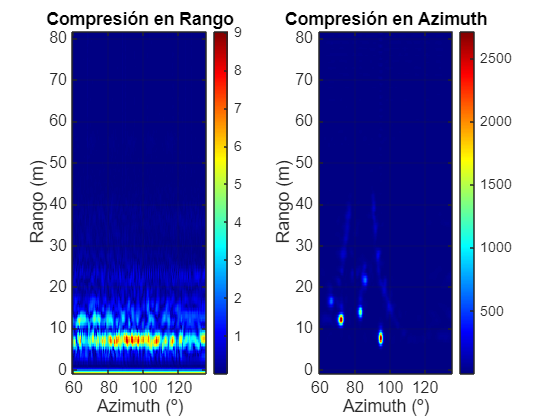

% % Graficar los valores digitales de la brújula
% figure;
% plot(bitsDigitales, 'LineWidth', 1.5);
% hold on; grid on;
% title('Señal brújula');
% xlabel('Muestra');
% ylabel('Valor');

% disp('Valores decodificados al encontrar fin de línea (usando str2double):');
% disp(valores);

% Graficar los valores originales
% figure;
% plot(valores, 'LineWidth', 1.5);
% hold on; grid on;
% title('Variación de los grados de la brújula ');
% xlabel('Índice de Medición');
% ylabel('Grados');

set(0, 'DefaultAxesFontSize', 13);
set(0, 'DefaultTextFontSize', 13);

figure,
subplot(1,2,1)
imagesc(anglesOfRamps,ejeR,(Sgn_fftMod));
set(gca,'YDir','normal')
colormap jet; colorbar
title('Compresión en Rango')
xlabel('Azimuth (º)')
ylabel('Rango (m)'), grid on

subplot(1,2,2)
imagesc(anglesOfRamps,ejeR,(MatrizRecortada));
set(gca,'YDir','normal')
colormap jet; colorbar
title('Compresión en Azimuth')
xlabel('Azimuth (º)')
ylabel('Rango (m)'), grid on

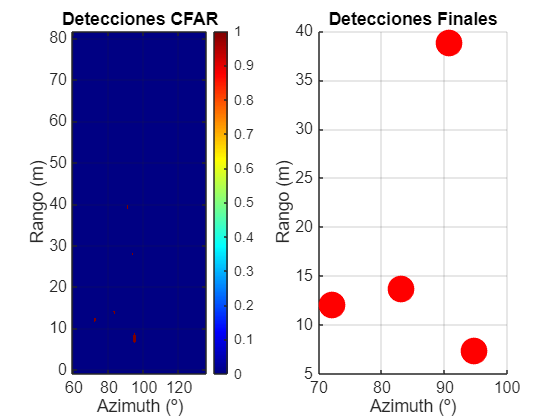


%%
% Crear una nueva figura con subplots
figure;

% Primer subplot: Mapa de detecciones CFAR
subplot(1, 2, 1);
imagesc(anglesOfRamps, ejeR, Detecciones);
set(gca, 'YDir', 'normal'); % Asegura que el eje Y esté orientado hacia arriba
colormap(gca, 'jet'); % Aplica el colormap 'jet' solo a este subplot
colorbar; % Añade una barra de color
xlabel('Azimuth (º)');
ylabel('Rango (m)');
title('Detecciones CFAR');
grid on;

% Segundo subplot: Detecciones finales
subplot(1, 2, 2);
scatter(ejeX, ejeY, 400, 'r', 'filled'); % Marcadores rojos rellenos
set(gca, 'YDir', 'normal');
xlabel('Azimuth (º)');
ylabel('Rango (m)');
title('Detecciones Finales');
grid on;